#### Phase 2: Biffurcation

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_Three_Pipes_height_50um
r_sensor=2 mm
Q_inlet_CNN=5 uL/min
height_pipe=50 um
c_Tartrazine_exp=0.08455 mol/L


c_max = 1

c_inlet=0.001 mol/L


mu = 9.9792e-04

D_coeff=4.9e-10 m^2/s


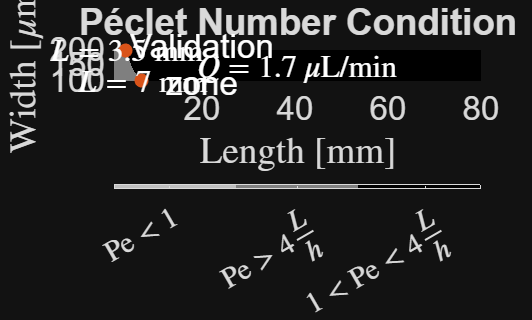

ans = 26.1799

w_Pipe_min=942.4778 um
w_Pipe_min=1 mm


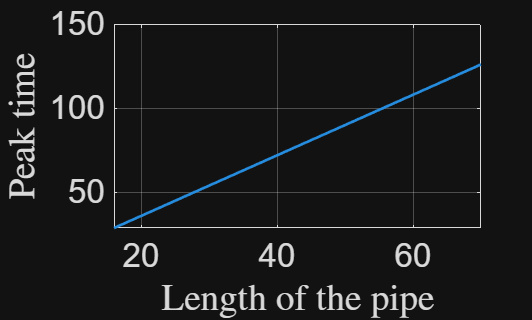

L_1 = 0.0160

L_2 = 0.0220

L_3 = 0.0335

    branch      L_m         Q_m3s          v_ms         Pe       Deff_m2s     t_pred_s    t_target_s
    ______    ________    __________    __________    ______    __________    ________    __________

      1       0.014624    3.6463e-11    0.00072927    74.415    1.4057e-08       20           20    
      2       0.020668      2.58e-11      0.000516    52.653    7.2822e-09       40           40    
      3       0.025308     2.107e-11     0.0004214        43    5.0201e-09       60           60    



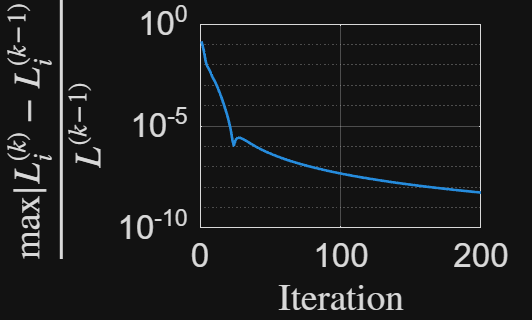

V_sensor/V_CNN =20.7366 %


v_char = 5.5556e-04

Pe = 56.6893

D_eff = 8.3635e-09

v_char = 5.5556e-04

Pe = 56.6893

D_eff = 8.3635e-09

v_char = 5.5556e-04

Pe = 56.6893

D_eff = 8.3635e-09

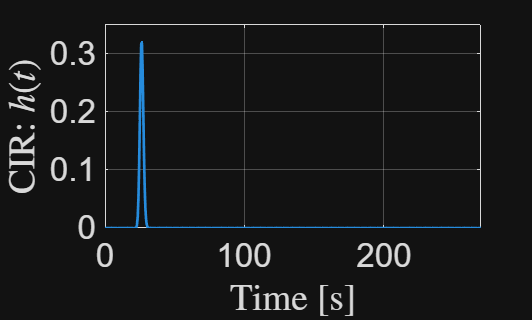

w_0=98.99500000 umL_0=0.21000000 mm

Pu311_x = -2.5863e-04

Pu333_x = 0.0149

Synthesis_Three_Pipes_Phase_1

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_Three_Pipes_height_50um
r_sensor=2 mm
Q_inlet_CNN=5 uL/min
height_pipe=50 um
c_Tartrazine_exp=0.08455 mol/L


c_max = 1

c_inlet=0.001 mol/L


mu = 9.9792e-04

D_coeff=4.9e-10 m^2/s


time_delta = 0.5000

ans = 20

ans = 19.5000

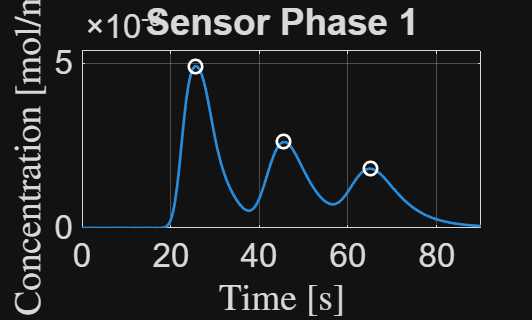


Analysis_Phase_1

#### 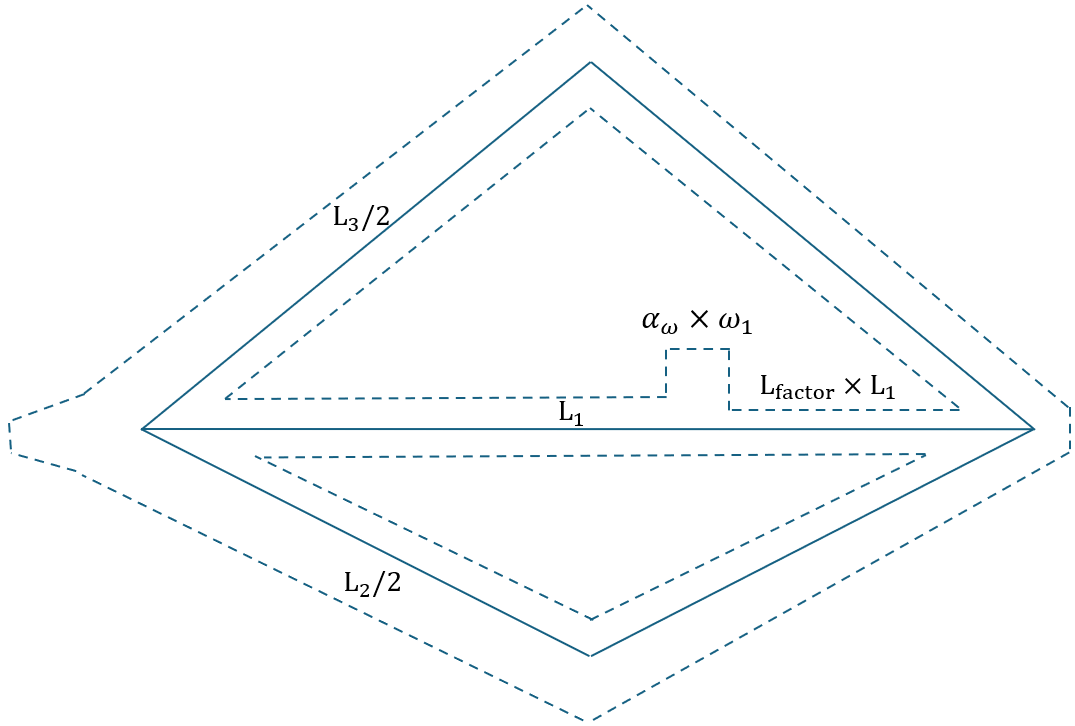

Fig 2: Illustration of reference parameters $\alpha_\omega$ and $\mathrm{L}_\mathrm{factor}$

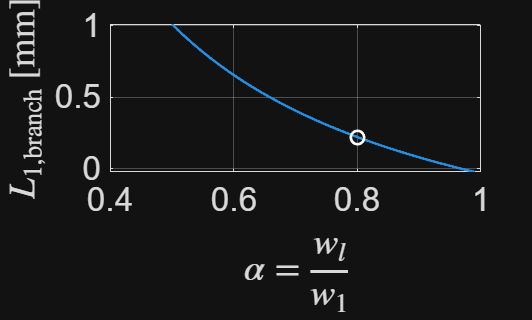

%Main parameters
alpha_molecules=0.7; %implements a further reduction of the number of molecules that travels to the outlet of Pipe 1, the lowest the value the less the molecules through pipe 1
alpha_w=0.8;%controls the width of the Pipe 1, the largest the value the largest the molecules at the outlet of Pipe 1

L_factor=1/5;%controls the position of the branch as a factor of the length of Pipe 1

%Evaluating the flow rate
%fraction of the reduced amplitude for pipe 1
f_molecules_Phase_1=alpha_molecules*h_COMSOL_CNN_Phase_1(t_peak_C_COMSOL)/h_COMSOL_CNN_Phase_1(t_peak_A_COMSOL);
%fraction of the width of pipe 1
alpha_array=linspace(0.5,0.99,1000);
%length of the upper branch
L_1_branch_array=zeros(1,length(alpha_array));


L_1_lower=L_factor*L_1;

for i=1:length(alpha_array)
    w_1_lower_biff=alpha_array(i)*w_1;
    w_1_upper_biff=(1-alpha_array(i))*w_1;
    
    %evaluation of the length of the upper biffurcation
    L_1_branch_array(i)=f_molecules_Phase_1/(1-f_molecules_Phase_1)*L_1_lower*w_1_upper_biff/w_1_lower_biff*(1-0.63*height_pipe/w_1_upper_biff)/(1-0.63*height_pipe/w_1_lower_biff);

end
%Selecting one specific value for alpha
[~,idx]=min(abs(alpha_array(:)-alpha_w));
L_1_branch=L_1_branch_array(idx);
alpha_branch=alpha_array(idx);

figure;
plot(alpha_array,L_1_branch_array*1e3,'LineWidth',2);grid on; hold on
plot(alpha_branch,L_1_branch*1e3,'ow','LineWidth',2,'MarkerSize',10)
xlabel('$\alpha=\frac{w_l}{w_1}$','Interpreter','latex');
ylabel('$L_{1,\mathrm{branch}}$ [mm]','Interpreter','latex');
set(gca,'FontSize',fontsize)


%Saving the results


Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, f_molecules_Phase_1, "", "Factor of reduced number of molecules");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, L_factor, "", "Factor of Length L_1 to determine the lenght of the lower biffurcation pipe");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, L_1, "m", "Length of Pipe_1");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, w_1, "m", "Width of Pipe 1");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, L_1_branch, "m", "Lenght of upper biffurcation");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, alpha_branch, "", "factor of w_1 for the biffurcation");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

#### Phase 2: Synthesis 

# CAD design of the CNN-like structure

**Description:** This code evaluates the coordinates for the upper lines and lower lines for each pipe. As represented on Fig. 1, we define each pipe coordinates with points.

## Center shape

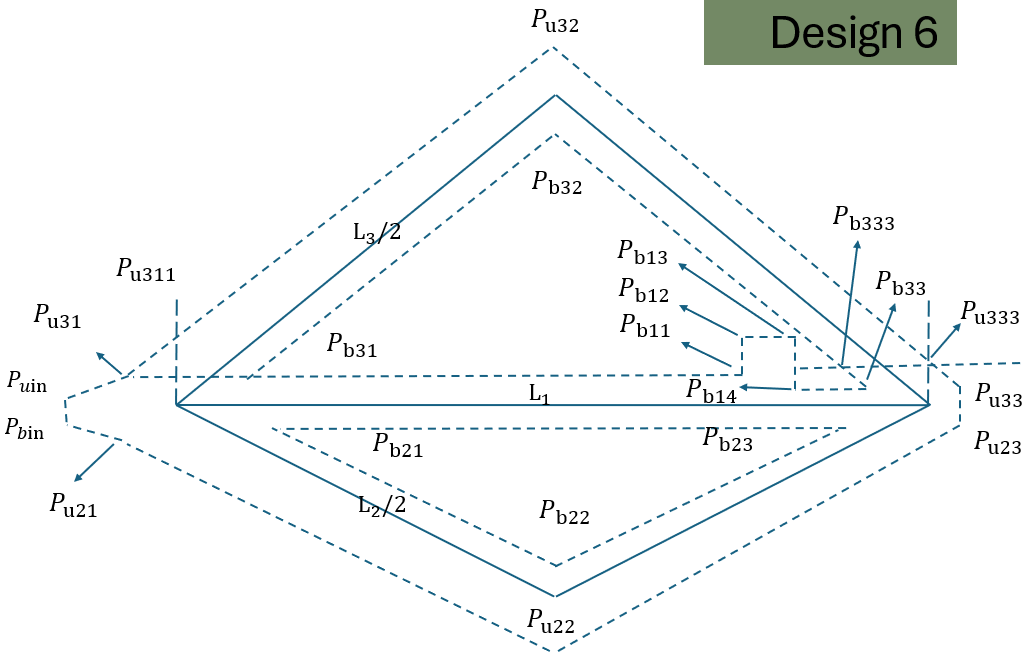

Figure 2: Reference points on the design.

### Inlet dimensions

%this reference coordinates are coming from the original CAD desing. This
%two points reference refer to the pipe just after the mixer on the
%transmitter side. See Fig. 1.
% P_u0=[-42.36063776 1.75826183]*1e-3;
% P_b0=[-42.36063776 1.65926683]*1e-3;
%width for the mixer pipe, this is taken from [4]
% w_0=P_u0(2)-P_b0(2);
w_0=98.995*1e-6;%measured with the design COMSOL_3D_CNN_Design_1_2.mph, placed at \COMSOL_CNN_height_38um_Q_2_2_uL_tetrazine_Design_1\CAD_design
fprintf('w_0=%.8f um', w_0*1e6);   % fixed-point with 15 decimals

w_0=98.99500000 um

%length of the inlet
L_0=210e-6;
fprintf('L_0=%.8f mm', L_0*1e3);   % fixed-point with 15 decimals

L_0=0.21000000 mm

### Center coordinates for the two top and bottom triangles in Figure 2

% basic validity checks (optional)
if L_3 < L_1 || L_2 < L_1
    error('Need L2 >= L1 and L3 >= L1 to form valid isosceles triangles.');
end

% base endpoints
Pc31 = [0, 0];
Pc33 = [L_1, 0];

% heights of upper and lower triangles
h_3 = sqrt( (L_3/2)^2 - (L_1/2)^2 );
h_2 = sqrt( (L_2/2)^2 - (L_1/2)^2 );

% height of upper triangle
Pc32 = [L_1/2,  h_3];

% height of lower triangle
Pc22 = [L_1/2, -h_2];

% Pu311
Pu311 = [0, (w_3 * L_3) / (2 * L_1)];
% Pu333
Pu333 = [L_1,  (w_3 * L_3) / (2 * L_1)];
% Pu211
Pu211 = [0, - (w_2 * L_2) / (2 * L_1)];

%Center polygon
% % Stack all vertices row by row
% coords = [Pc31; Pc32; Pc33; Pc22; Pc31; Pc33];
% %saving in the CSV file
% outputFile = fullfile(pwd, 'dataset', 'polygon_center.csv'); % build full path safely
% writematrix(coords, outputFile);

#### Upper polygon

% Inner triangle vertices

% Pb32: intersection of the two offset slanted sides
x_b32 = L_1/2;
y_b32 = h_3 - (w_3 * L_3) / (2 * L_1);
Pb32  = [x_b32,  y_b32];

% Pb31: left bottom vertex (offset left side & y = w_1/2)
x_b31 = (L_3 * w_3 + L_1 * w_1) / (4 * h_3);
y_b31 =  w_1 / 2;
Pb31  = [x_b31,  y_b31];

%Pb11
Pb11=Pb31+[L_1-L_1_lower,0];

%Pb12
Pb12=Pb11+[0,L_1_branch];

%Pb13
Pb13=Pb12+[(1-alpha_branch)*w_1,0];

%Pb14
Pb14=Pb13+[0,-L_1_branch-(1-alpha_branch)*w_1];

% Pb333: right bottom vertex (offset right side & y = w_1/2)
x_b333 = L_1 - x_b31;
y_b333 =  w_1 / 2;
Pb333  = [x_b333,  y_b333];

% Pb33: right bottom vertex (offset right side & y = w_1/2)
Pb33_x=Pb333(1)+(w_1/2-Pb333(2))*(Pb32(1)-Pb333(1))/(Pb32(2)-Pb333(2))

Pb33_x = 0.0137

Pb33=[Pb33_x ,Pb14(2)];


%Upper polygon
% Stack all vertices row by row
coords = [Pb31; Pb11; Pb12; Pb13; Pb14; Pb33; Pb32];
%saving in the CSV file
outputFile = fullfile(pwd, 'datasets', 'polygon_upper_Phase_2.csv'); % build full path safely
writematrix(coords, outputFile);


#### Bottom Polygon

% height of lower outer triangle
h_2 = sqrt( (L_2/2)^2 - (L_1/2)^2 );

% ---- inner lower triangle vertices ----

% Pb21: left top vertex (offset left side & y = -w_1/2)
x_b21 = (L_2 * w_2 + L_1 * w_1) / (4 * h_2);
y_b21 = -w_1 / 2;
Pb21  = [x_b21, y_b21];

% Pb22: apex of inner lower triangle
x_b22 = L_1 / 2;
y_b22 = -h_2 + (L_2 * w_2) / (2 * L_1);
Pb22  = [x_b22, y_b22];

% Pb23: right top vertex (offset right side & y = -w_1/2)
x_b23 = L_1 - x_b21;
y_b23 = -w_1 / 2;
Pb23  = [x_b23, y_b23];

%Bottom polygon 
% Stack all vertices row by row
coords = [Pb21; Pb22; Pb23; Pb21];
%saving in the CSV file
outputFile = fullfile(pwd, 'datasets', 'polygon_bottom_Phase_2.csv'); % build full path safely
writematrix(coords, outputFile);



#### Outer polygon

% Pu32
Pu32 = [L_1/2, h_3 + (w_3 * L_3) / (2 * L_1)];
% Pu22
Pu22 = [L_1/2, -h_2 - (w_2 * L_2) / (2 * L_1)];



% Pu31
Pu311_x=Pu311(1)+(w_1/2-Pu311(2))*(Pu32(1)-Pu311(1))/(Pu32(2)-Pu311(2))

Pu311_x = -2.5863e-04

Pu31=[Pu311_x , w_1/2];
% Pu21
Pu21=[Pu311_x , -w_1/2];
% Pu33
Pu333_x=Pu333(1)+(w_1/2-Pu333(2))*(Pu32(1)-Pu333(1))/(Pu32(2)-Pu333(2))

Pu333_x = 0.0149

Pu33=[Pu333_x , w_1/2];
% Pu23
Pu23=[Pu333_x , -w_1/2];

%P_bin
Pbin=[-L_0/2,-w_0/2];
%P_uin
Puin=[-L_0/2,w_0/2];


%Outer polygon 
% Stack all vertices row by row
coords = [Pu31; Pu32; Pu33; Pu23; Pu22; Pu21; Pu31];
%saving in the CSV file
outputFile = fullfile(pwd, 'datasets', 'polygon_outer_Phase_2.csv'); % build full path safely
writematrix(coords, outputFile);

Pu23_x=Pu23(1);
Pu23_y=Pu23(2);

Pu33_x=Pu33(1);
Pu33_y=Pu33(2);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Pu23_x, "m", "Width of Pipe 1");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Pu23_y, "m", "Width of Pipe 1");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Pu33_x, "m", "Width of Pipe 1");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Pu33_y, "m", "Width of Pipe 1");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

%===============Helpers========================

function writeComsolParamCSV(filename, T)
    % Writes the 3-column cell array back to CSV
    writetable(T, filename, "Delimiter", ",","WriteVariableNames", false);
end


function T = upsertParamFromVar(T, var, unit, desc)
%UPSERTPARAMFROMVAR Upsert a COMSOL parameter row using MATLAB variable name.
%
% Usage:
%   T = upsertParamFromVar(T, myVar, "mol/m^3", "Description");
%   T = upsertParamFromVar(T, myVar, "",        "Description");  % no unit

    name = inputname(2);
    if isempty(name)
        error("upsertParamFromVar: Could not infer variable name. Use upsertParamTable with explicit name.");
    end

    % If unit is omitted or passed as empty, treat as no-unit
    if nargin < 3 || isempty(unit) || (isstring(unit) && strlength(unit)==0) || ...
                     (ischar(unit) && strlength(string(unit))==0)
        unit = "";
    end

    % Desc can be omitted too
    if nargin < 4 || isempty(desc)
        desc = "";
    end

    T = upsertParamTable(T, string(name), var, unit, desc);
end


function T = upsertParamTable(T, name, value, unit, desc)
%UPSERTPARAMTABLE Insert or overwrite a parameter row (name, expr, desc)
% in a 3-column table T.

    name = string(name);

    % Normalize unit/desc robustly
    unit = normalizeTextScalar(unit);
    desc = normalizeTextScalar(desc);

    expr = buildComsolExpr(value, unit);

    % Find existing entry in first column
    idx = find(string(T{:,1}) == name, 1, "first");

    if isempty(idx)
        % Append new row (assign all columns)
        newRow = {name, expr, desc};
        T = [T; cell2table(newRow, "VariableNames", T.Properties.VariableNames)];
    else
        % Overwrite existing row
        T{idx,1} = name;
        T{idx,2} = expr;
        T{idx,3} = desc;
    end
end


function expr = buildComsolExpr(value, unit)
%BUILDCOMSOLPR Build "value[unit]" or "value" if unit is empty.

    unit = normalizeTextScalar(unit); % ensures "" if empty/whitespace/etc.

    if isnumeric(value)
        if ~isscalar(value)
            error("buildComsolExpr: value must be scalar for COMSOL parameters.");
        end
        valStr = string(num2str(value, "%.15g"));
    else
        valStr = string(value); % keep expressions as text
    end

    if strlength(unit) == 0
        expr = valStr;
    else
        expr = valStr + "[" + unit + "]";
    end
end


function s = normalizeTextScalar(x)
%NORMALIZETEXTSCALAR Convert x to a clean string scalar.
% - [] / missing / whitespace-only -> ""
% - char/string -> trimmed string scalar

    if nargin == 0 || isempty(x)
        s = "";
        return;
    end

    % Handle missing string
    if isstring(x) && isscalar(x) && ismissing(x)
        s = "";
        return;
    end

    s = string(x);
    if numel(s) ~= 1
        error("Expected a single unit/description text value, got %d elements.", numel(s));
    end

    s = strtrim(s);
    if ismissing(s)
        s = "";
    end
end